# ECSE 343 Final Exam Question 2 (10 Marks)

Posted at 9:00AM April 19, 2021

Due at 9:00AM April 22, 2021

**This final has three Questions. Each question is submitted as a seperate 'assignment'.** 

## ** Question 2**

Question two is very similar to question 1 but with different set of data. In this case as well, you know that Ydata contains zero-mean gaussian noise. 

You may run the following code in order to display the data (make sure Q2data.mat is in your working directory):

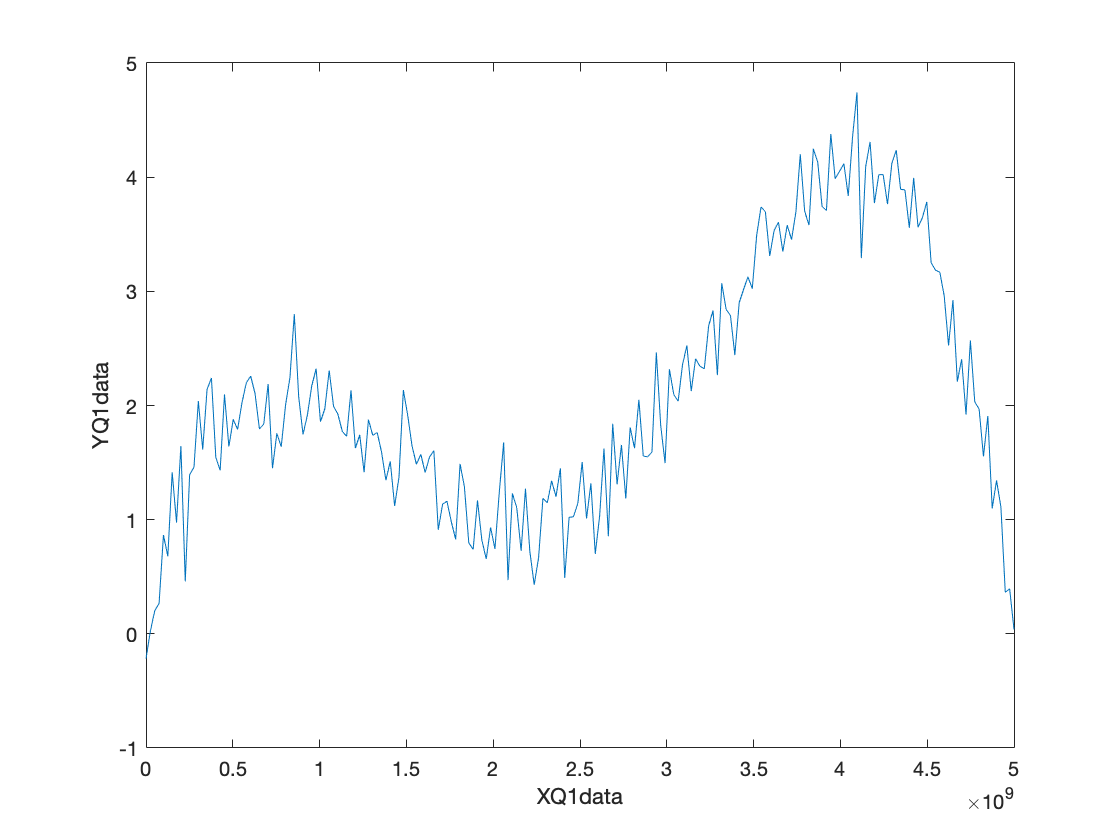

clear all
clf
load Q2data

plot(Xdata,Ydata)
xlabel('XQ1data')
ylabel('YQ1data')

**Part 1 (5 Marks)**

Use the techniques we studied in this course in order to find a plot a better estimate of Ydata and store it in Yest. You may use (if needed) the following matlab builtin functions: qr, lu, chol, svd, eig, polyval, and the '\' operator as in x = A\b. Feel free to copy and include any code you used in Question 1 that you deem useful for this question. Include and run your code below

% Load and plot original data
clear all
clf
load Q2data  %make sure Q2data.mat is in your current directory

%% Your code to compute Yest should go below

%fitting polynomial degree
deg = 4;

%evaluate polynomial matrix 
M = zeros(size(Xdata,2), deg+1);
for i=1:size(M)
     x = Xdata';
     M(i,:) = x(i);
     M(i,:) = M(i, :) .^ (0:1:deg);
end

cond(M)

ans = 2.0028e+40


%cholesky 
%(M'M)*A = (M'*Ydata')

A = (M' * M) \ (M' * Ydata');

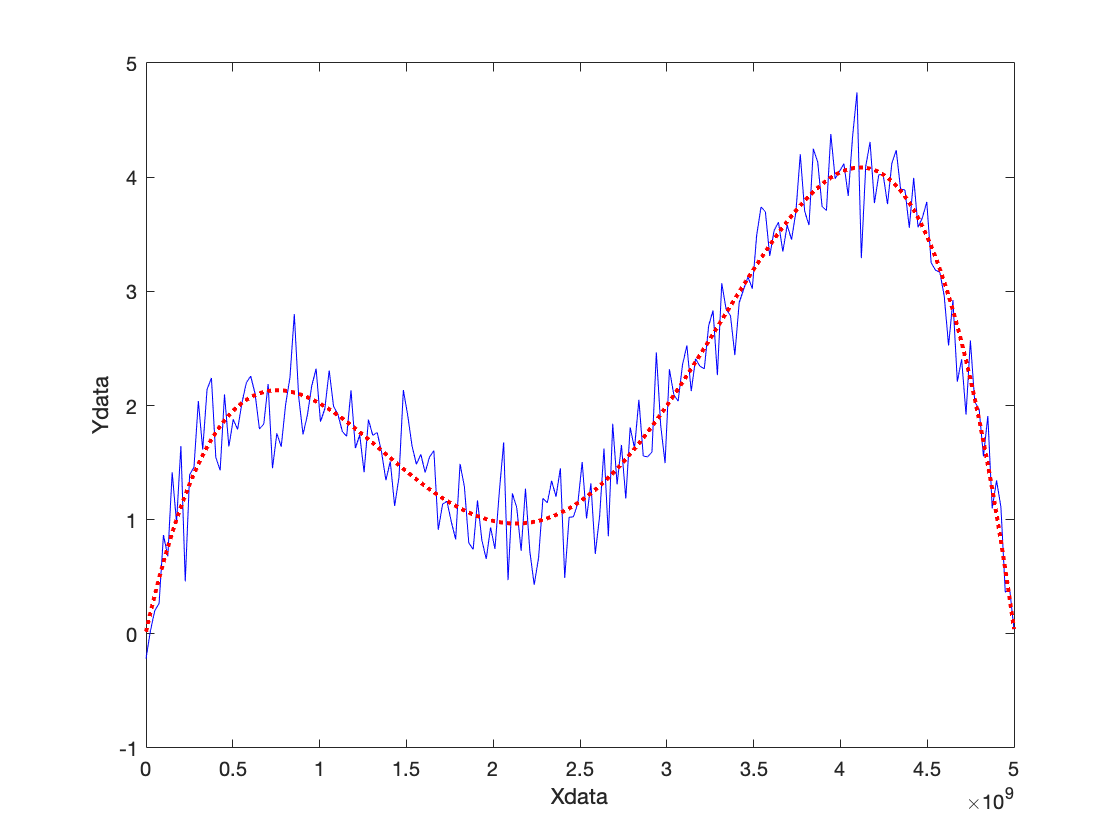


%Solve for Y
Yest = zeros(length(Xdata'),1);
powers = 0:deg;
for I = 1:length(powers)
   Yest = Yest + A(I)*Xdata'.^powers(I);
end


% Plot the results of your estimate and compare to original data
% The code below assumes you have already computed Yest 
plot(Xdata,Ydata,'b')
xlabel('Xdata')
ylabel('Ydata')
hold on
plot(Xdata,Yest,'r:','LineWidth',2)

**Part 2 (5 Marks)**

What accuracy improvement method was more important in Question 2 than it was in Question 1? (note that some of you may have already incorporated this in their answer for question 1 even if it was less critical there). Explain why it is important.You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.

In this case, the matrix X is ill-conditioned due the large size of entries of the X vector used to create the polynomial matrix. To solve the system in this case, a simple matrix inverse, LU or QR will not work due to the loss of numerical precision when performing computations with large numbers. 

To get around this issue, Cholesky or SVD can be used. In this case, Cholesky to solve the normal equation. As the polynomial matrix is symmetric positive definite, there arer no zero pivots, so Cholesky is well suited for the task. 